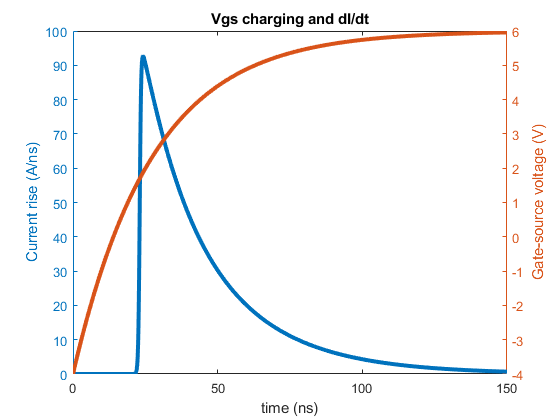

t = (0:1500)*0.1e-9;
Vgh = 6;
Vgl = -4;
Ron = 20;
Ciss = 1367e-12;
Vgs = (Vgh - Vgl)*(1-exp(-t./(Ron*Ciss))) + Vgl;


Tj = 25; % + 100/150e-9*t;
K1 = 90.8-0.387*(Tj - 25);
K2 = 1/26;
K3 = 1.1;
K4 = 1.1;
K5 = 1;
Vth = 1.7;

h = exp((Vgs - Vth)./K2);

dIdVgs = K1./(Vgs + K3 + K5).*((h./K2)./(1+h) + log(1+h)./(Vgs+K3+K5));
dVgsdt = (Vgh - Vgl)/(Ron*Ciss)*exp(-t./(Ron*Ciss));
dIdt = dIdVgs.*dVgsdt;

figure
title('Vgs charging and dI/dt')
yyaxis left
plot(t*1e9,dIdt/1e9,'LineWidth',3)
ylabel('Current rise (A/ns)')
yyaxis right
plot(t*1e9,Vgs,'LineWidth',3)
ylabel('Gate-source voltage (V)')
xlabel('time (ns)')